# Rubber Band-Ball Simulator

### By: Arnaldo Rodriguez-Gonzalez

- This MATLAB Live Script is intended to give you a physical sense of what the motion of a ball of mass $m=1$kg suspended on a rubber band with spring constant $k=1$ N/m and rest length $L_0 \approx 8$ m looks like.

- Move the slider around to change the initial vertical position of the ball, and press the button to watch the simulation in real-time!

- The simulation tracks time through a computer clock, so the animation may stutter a bit and/or present inaccurate time-position values for slow computers.

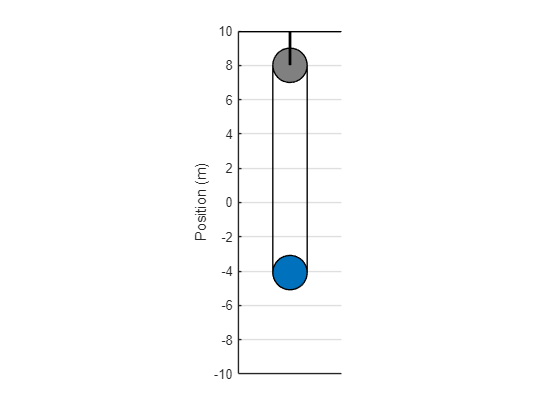


% Remove all pre-existing stuff
clear
close all
% Select the initial condition
y0 = -5.52;
% Run all of the code when pressing the button
 
% Assign the endpoint of the rubber band to be the ball position when in
% tension, or its rest length when not in tension.
if y0 > 0
    bandpos = 0;
else
    bandpos = y0;
end
% Solve the ODE for this problem with given initial conditions for 20
% seconds.
[t,y] = ode15s(@(t,y)bandnspring(t,y),linspace(0,20,10000),[y0; 0]);
% Draws the ball.
a = rectangle('Position',[-1 y0-1 2 2],'Curvature',[1 1],'FaceColor',[0, 0.4470, 0.7410]);
% Draws the rubber band.
b = rectangle('Position',[-1 bandpos-1 2 10-bandpos],'Curvature',1);
% Draws the "support" ball.
c = rectangle('Position',[-1 7 2 2],'Curvature',[1 1],'FaceColor',[0.5, 0.5, 0.5]);
% Draws the other two support lines.
d = line([0 0],[8 10]);
d.LineWidth = 2;
f = line([-3 3],[10 10]);
f.LineWidth = 2;
d.Color = 'k';
f.Color = 'k';
% This sets plot settings (like axis limits, etc.)
h = gcf;
axis equal
axis([-3 3 -10 10])
grid on
xticks([])
ylabel('Position (m)')
% Commences an internal computer clock to be stored in "tr".
tic
tr = 0;
% Loops while the computer clock is more than a second away from the
% simulated final time.
while tr <= max(t)-1
    % Updates computer clock time.
    tr = toc; 
    % Finds position at current computer clock time.
    yt = interp1(t,y(:,1),tr);
    % Calculates correct rubber band endpoint based on tension criteria.
    if yt > 0
        bandpos = 0;
    else
        bandpos = yt;
    end
    % Update ball and rubber band position values.
    a.Position = [-1 yt-1 2 2];
    b.Position = [-1 bandpos-1 2 10-bandpos];
    % Update plot.
    drawnow
end

function dydt = bandnspring(t,y);
% Turns off the spring force if the rubber band is not in tension: i.e. if
% y > 0.
if y(1) > 0
    k = 0;
else
    k = 4;
end
dydt = [y(2); -k*y(1) - 9.81];
end % end of rhs function

## Activities:

- Move the slider around a bit. Can you divide the initial conditions you input with the slider into two specific "types" based on what you observe?

- Can you identify, in terms of your initial condition, when the transition between either "type" of motion occurs?

- Try to justify this transition using a free-body diagram and a physical set-up of the ball and the rubber band. Be precise!

- Using the set-up you constructed above, try to find the equations of motion for both motion regimes that you observe in the simulation.

- Calculate the oscillation period of the ball for the regime when it always stays on the rubber band. Compare your analytical result with what you can measure from the simulation using a stopwatch. (They should line up nicely if your animation isn't lagging too much.)

- How different is the oscillation period you found above from what you'd find if the mass was connected to the ceiling by a spring with spring constant $k=1$ N/m? Is the ratio of periods a function of $k$?

- Calculate the oscillation period of the ball for the other regime of motion. This is a tricky problem!